### Splot jako metoda filtracji sygnałów

Operacja splotu ma wiele zastosowań, jednak w przetwarzaniu sygnałów (i obrazów) jest stosowana najczęściej jako metoda filtracji. Za pomocą prostych filtrów można zrealizować m.in. operacje wygładzania sygnału, wyostrzania czy detekcji krawędzi. W ramach przykładu stworzymy sygnały sinusoidalny oraz prostokątny, które następnie aszumimy:

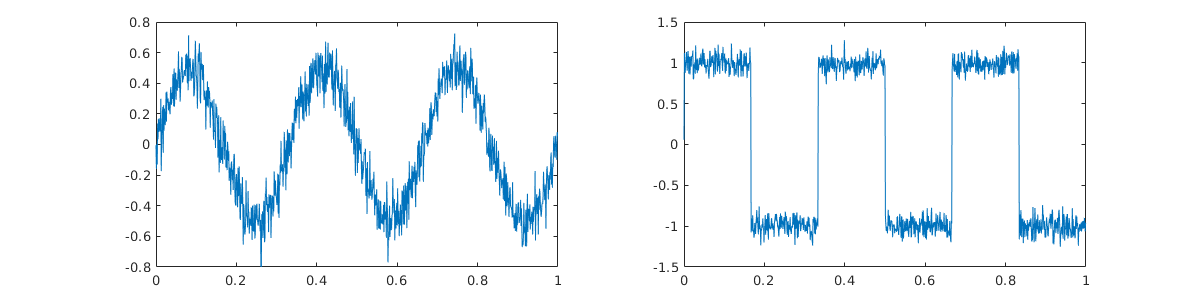

t=0:0.001:0.999;
sig_1 = 0.5*sin(6*pi*t) + 0.1 * randn(1, 1000);
sig_2 = sign(0.5*sin(6*pi*t)) + 0.1 * randn(1, 1000);

twoplots(t, sig_1, sig_2);

#### Filtr uśredniający

Charakter sygnału jest dość dobrze widoczny, jednak szum może przeszkadzać w jego analizie. Najprostszą metodą przetworzenia takiego sygnału jest uśrednienie wartości w pewnym oknie, dzięki czemu szum zostanie stłumiony. Filtr taki nazywamy filtrem średniej kroczącej, a jego realizacja przy użyciu splotu wymaga stworzenia bardzo prostego jądra. Filtr o rozmiarze N ma postać [1/N, 1/N, ..., 1/N]. Im dłuższy filtr stworzymy tym wygładzanie będzie lepsze, ale jednocześnie szybkie zmiany sygnału zostaną stłumione:

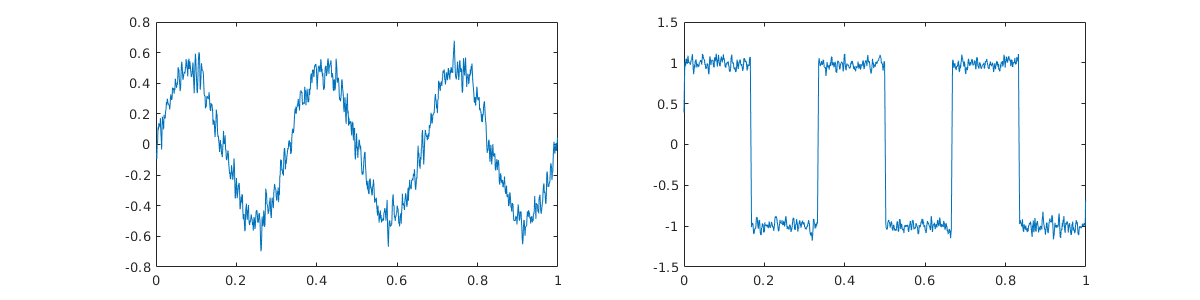

f3 = ones(1,3) / 3;
c3_1 = conv(sig_1, f3, 'same');
c3_2 = conv(sig_2, f3, 'same');

twoplots(t, c3_1, c3_2);

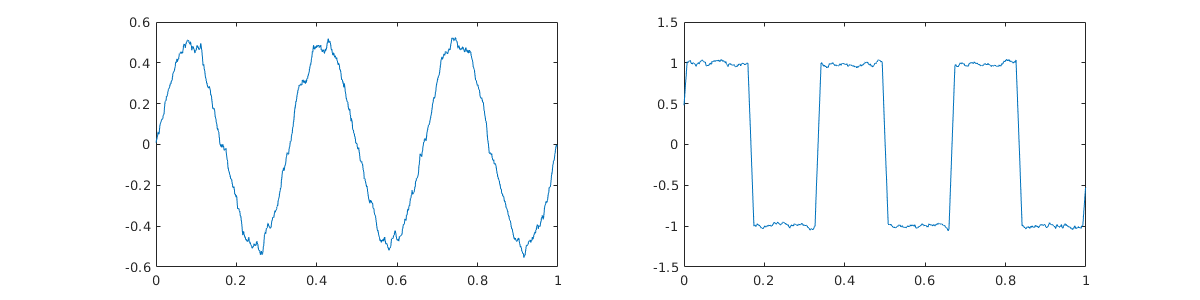

f15 = ones(1,15) / 15;
c15_1 = conv(sig_1, f15, 'same');
c15_2 = conv(sig_2, f15, 'same');

twoplots(t, c15_1, c15_2);

Zwiększenie wielkości filtra ma szczególnie widoczny wpływ na sygnał prostokątny, gdzie zbocze z pionowego zmieniło swoją stromość na dużo łagodniejsze. Inną wadę filtra uśredniającego można dostrzec po jego analizie częstotliwościowej. W skrócie: poddając jądro filtra przekształceniu do dziedziny częstotliwości możemy określić, jak filtr tłumi bądź wzmacnia poszczególne częstotliwości. Filtr wygładzający jest z natury filtrem dolnoprzepustowym, więc powinien przepuszczać niskie częstotliwości a tłumić wysokie. Spójrzmy więc na charakter najprostszego filtra 3-elementowego:

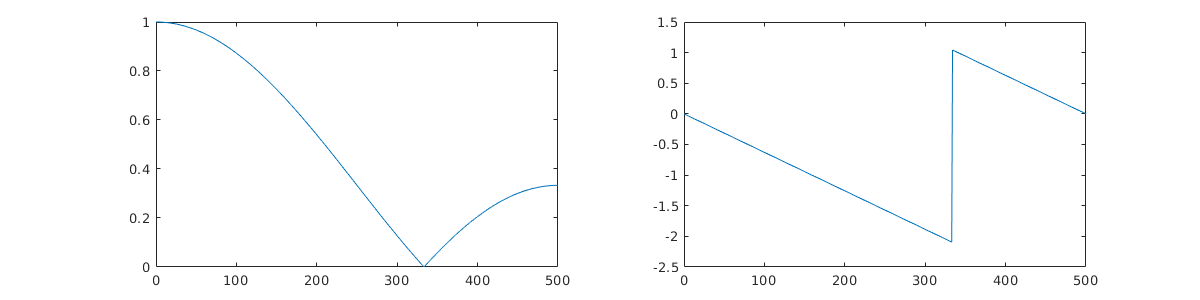

filtstat(f3);

Wykres amplitudowy możemy traktować jako wzmocnienie filtra dla różnych częstotliwości. Widać, że do ok. 2/3 skali faktycznie wzmocnienie spada, jednak później "odbija" się, a więc wyższe częstotliwości nie są całkowicie wygaszane. Co więdcej, stromość zbocza jest bardzo niska, więc filtr taki nie jest perfekcyjny. Zwiększając rozmiar filtra możemy wpłynąć na jego częstotliwość odcięcia (im dłuższy, tym niższa będzie częstotliwość odcięcia), jednak "dzwonienie" filtra pozostanie bez zmian.

#### Filtr Gaussa

Problemem filtra uśredniającego jest jednakowe traktowanie wszystkich punktów w danym oknie. Możemy przyjąć inne założenie, np, punkt centralny traktować jako najważniejszy, a im dalej od środka jądra tym wagę ustawiać na mniejszą. Popularnym rodzajem filtra tego typu jest filtr Gaussa. Dla trzech elementów jego dobrym przybliżeniem jest wektor [0.25, 0.5, 0.25], dla większych rozmiarów można użyć np. funkcji fspecial:

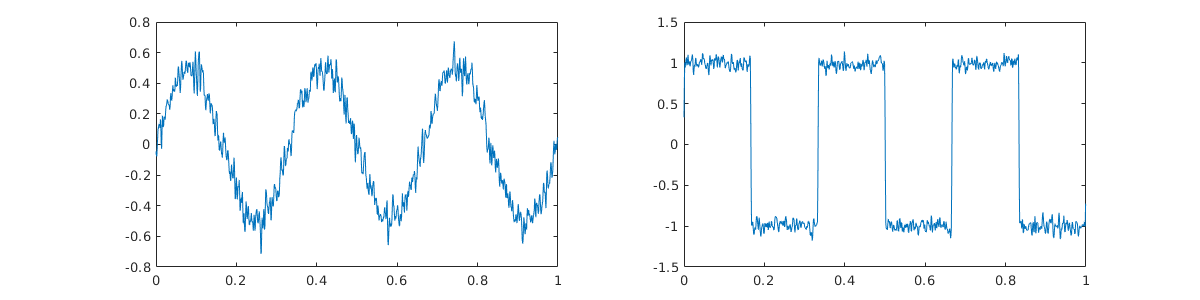

g3 = fspecial('gaussian', [1,  3], 1);
cg3_1 = conv(sig_1, g3, 'same');
cg3_2 = conv(sig_2, g3, 'same');

twoplots(t, cg3_1, cg3_2);

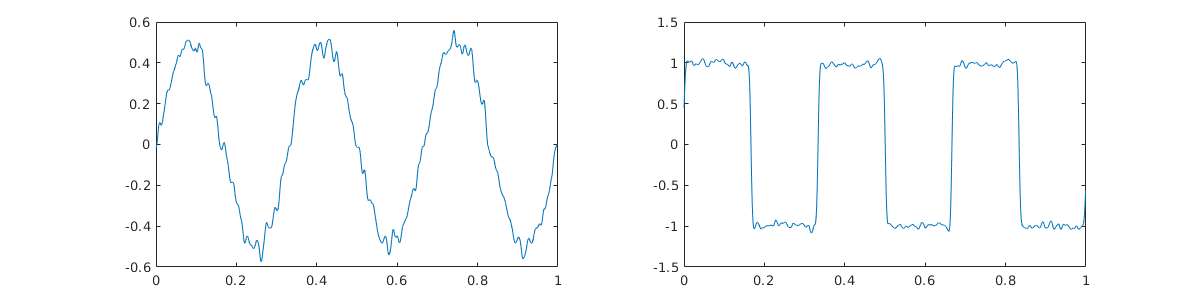

g15 = fspecial('gaussian', [1, 15], 3);
cg15_1 = conv(sig_1, g15, 'same');
cg15_2 = conv(sig_2, g15, 'same');

twoplots(t, cg15_1, cg15_2);

Filtr Gaussa ma dużo czystszą charakterystykę częstotliwościową, co widać nawet na przefilstrowanych sygnałach (nie ma fragmentów wysokich częstotliwości):

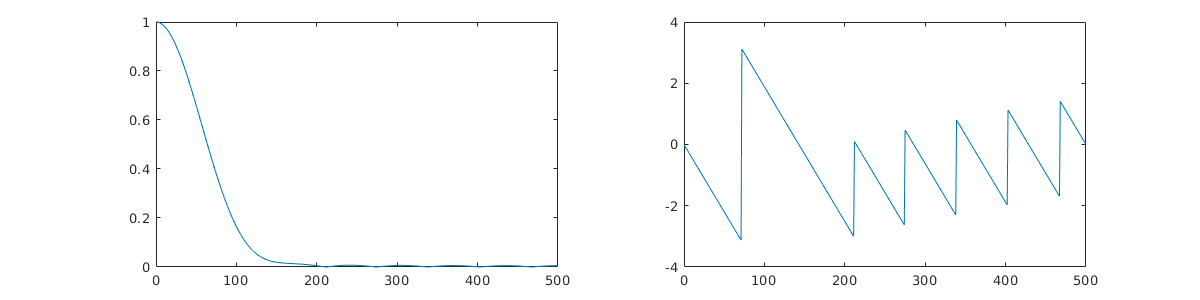

filtstat(g15);

Różnicę między filtrami uśredniającym i Gaussa widać szczególnie dobrze przy filtracji obrazów:

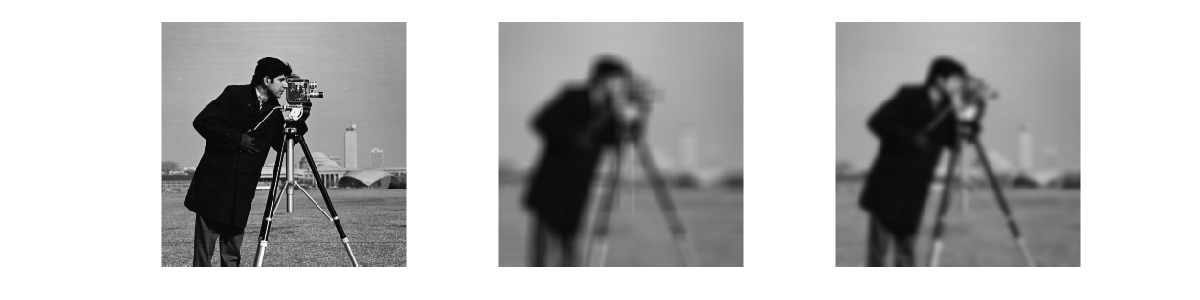

I=imread('cameraman.tif');

Ia = imfilter(I, fspecial('average', 15), 'replicate'); 
Ig = imfilter(I, fspecial('gaussian', 15, 3), 'replicate'); 

figure('Position', [10 10 1200 300]);
subplot(131);
imshow(I);
subplot(132);
imshow(Ia);
subplot(133);
imshow(Ig);

#### Detekcja zbocza

Inną grupą filtrów splotowych są filtry krawędziowe. Są to filtry górnoprzepustowe, których rolą jest wykrycie miejsc, gdzie zmiana sygnału jest duża. Zazwyczaj filtry takie sumują się do zera (w przeciwieństwie do wygładzających, które sumowały się do jedności), a najprostszym filtrem tego typu jest [1, 0, -1]:

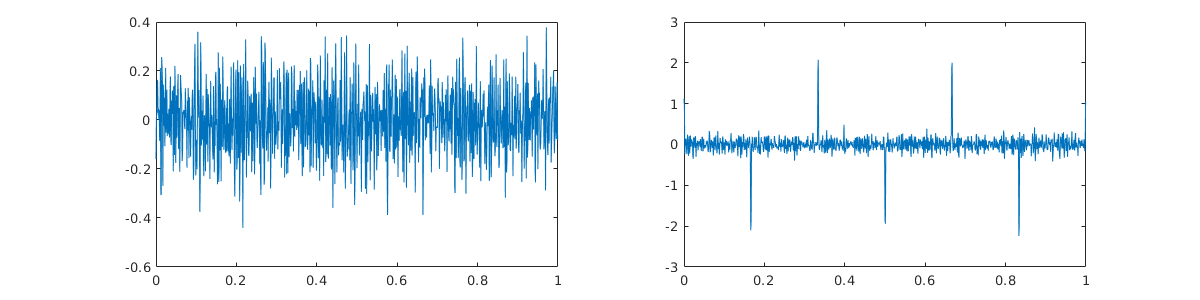

e3 = [1, 0, -1];

ce3_1 = conv(sig_1, e3, 'same');
ce3_2 = conv(sig_2, e3, 'same');

twoplots(t, ce3_1, ce3_2);

W przypadku sinusoidy odpowiedź jest zaszumiona, ale bez dużych skoków. Dla sygnału prostokątnego widać natomiast wyraźnie miejsca, w których sygnał miał zbocza opadające i narastające. Odpowiednie progowanie i dalsza analiza takiego sygnału pozwala na dość skuteczną detekcję zmian sygnału. 

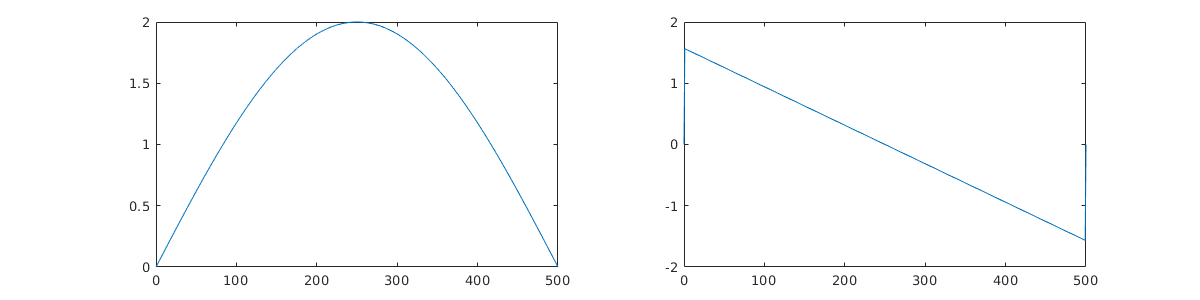

filtstat(e3);

### Autokorelacja jako metoda określania częstotliwości bazowej

Splot dwóch sygnałów jest swego rodzaju miarą ich podobieńśtwa. Jeśli dokonamy splotu sygnału z jego kopią, przesuniętą o pewną liczbę próbek, będizemy mogli wyznaczyć jego samopodobieństwo. Wykonując tę operację dla całego przedziału wartości, w których sygnał został spróbkowany, otrzymamy autokorelację sygnału. Im wyższa wartość na wykresie autokorelacji, tym większe podobieństwo sygnału do swojej własnej, przesuniętej kopii.

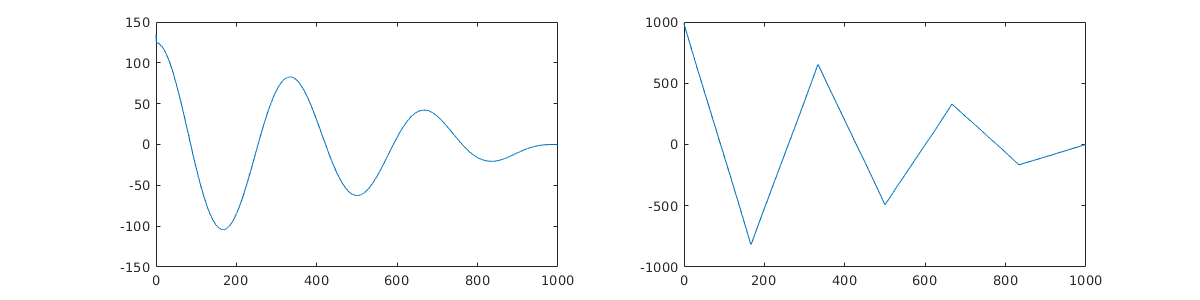

[r1, lags] = xcorr(sig_1);
[r2, lags] = xcorr(sig_2);

% wycięcie jedynie dodatnich przesunięć
r1 = r1(lags >= 0);
r2 = r2(lags >= 0);
lags = lags(lags>=0);

twoplots(lags, r1, r2);

Maksimum funkcji autokorelacji występuje zawsze dla zerowego przesunięcia - sygnał zawsze jest idealną kopią samego siebie w tym przypadku. Jeśli wykres posiada jakieś inne, wyraźne maksima lokalne może to sugerować, że ma on charakter okresowy. Pierwsze maksimum lokalne występujące dla niezerowego przesunięcia można przeliczyć na bazową częstotliwość sygnału (znając przesunięcie i częstotliwość próbkowania):

[pks, loc] = findpeaks(r1, "MinPeakDistance", 10, "MinPeakProminence", 20);
fs = 1000;

% przesunięcie w sekundach
lag_s = loc(1) * 1/fs;

% częstotliwość bazowa
freq = 1/lag_s

freq = 2.9940

function twoplots(t, s1, s2)
    figure('Position', [10 10 1200 300]);
    subplot(121);
    plot(t, s1);
    subplot(122);
    plot(t, s2);
end

function filtstat(f)
    nfft = 1000;
    fs = 1000;
    N = 3;
    
    f_ex = zeros(1, nfft);
    f_ex(1:size(f, 2)) = f;
    
    y=fft(f_ex);
    f_base = linspace(0, fs/2, nfft/2+1);
    amp = abs(y(1:nfft/2+1));
    phase = angle(y(1:nfft/2+1));
    
    twoplots(f_base, amp, phase);
end